# Visualization part 1

- line plot

- scatter

- histogram

- imagesc

- colormap

## Line Plot

Create `x` as a vector of linearly spaced values between 0 and $2\pi$. Use an increment of $\pi/100$ between the values. Create `y` as sine values of `x`. Create a line plot of the data.

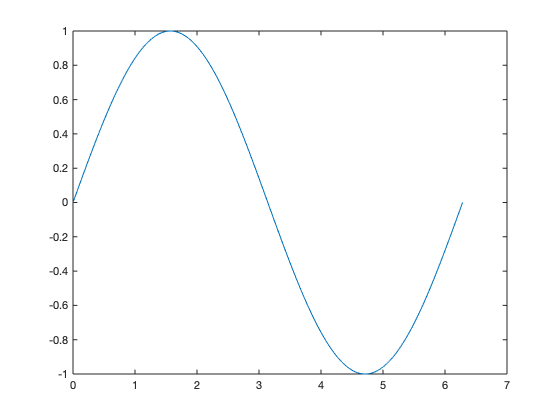

x = 0:pi/100:2*pi;
y = sin(x);
plot(x,y);

Define `x` as 100 linearly spaced values between −2*π* and 2*π*. Define `y1` and `y2` as sine and cosine values of `x`. Create a line plot of both sets of data.

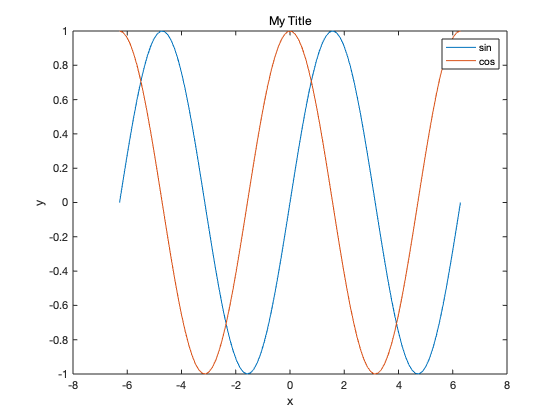

x = linspace(-2*pi,2*pi);
y1 = sin(x);
y2 = cos(x);

figure;
plot(x,y1,x,y2);
title('My Title');
xlabel('x');
ylabel('y');
legend({'sin', 'cos'});

## Scatter plot

Create `x` as 200 equally spaced values between 0 and 3*π*. Create `y` as cosine values with random noise. Then, create a scatter plot.

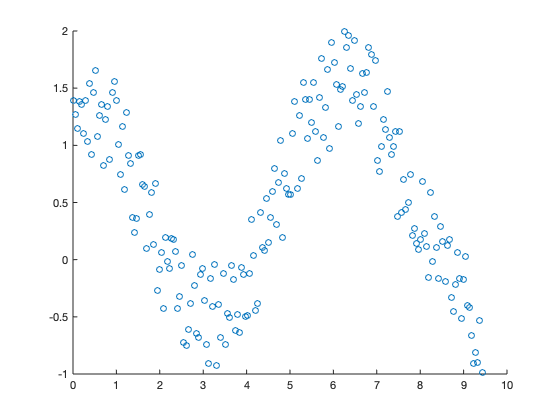

x = linspace(0,3*pi,200);
y = cos(x) + rand(1,200);  
scatter(x,y)

Create vectors `x` and `y` as sine and cosine values with random noise. Create a scatter plot and set the marker edge color, marker face color, and line width.

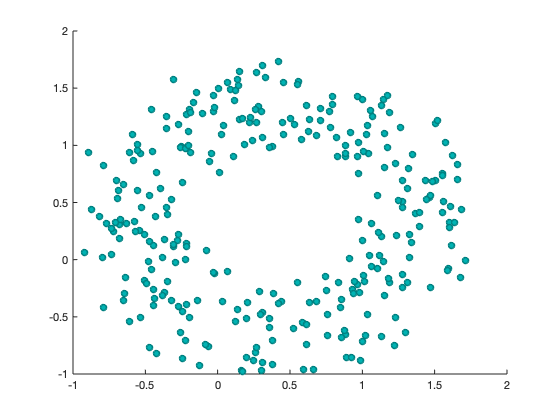

theta = linspace(0,2*pi,300);
x = sin(theta) + 0.75*rand(1,300);
y = cos(theta) + 0.75*rand(1,300);  
sz = 40;
scatter(x,y,sz,'MarkerEdgeColor',[0 .5 .5],...
              'MarkerFaceColor',[0 .7 .7],...
              'LineWidth',1.5)

## Histogram

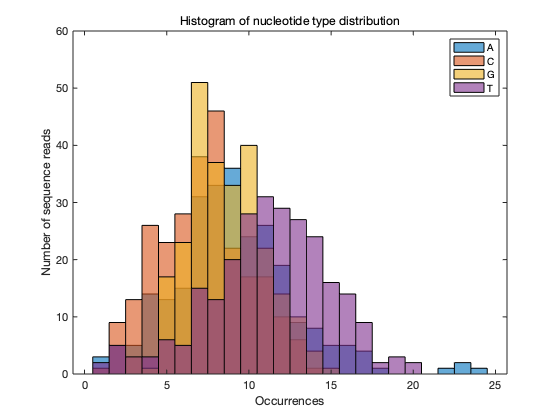

% Load nucleotide data
load nucleotideData ncount
% Create the histogram using the histogram function
figure
h1 = histogram(ncount(:,1));
hold on
histogram(ncount(:,2),h1.BinEdges)
histogram(ncount(:,3),h1.BinEdges)
histogram(ncount(:,4),h1.BinEdges)
hold off
% Add a legend
legend('A', 'C', 'G', 'T')
% Add title and axis labels
title('Histogram of nucleotide type distribution')
xlabel('Occurrences')
ylabel('Number of sequence reads')

## imagesc

Display image with scaled colors

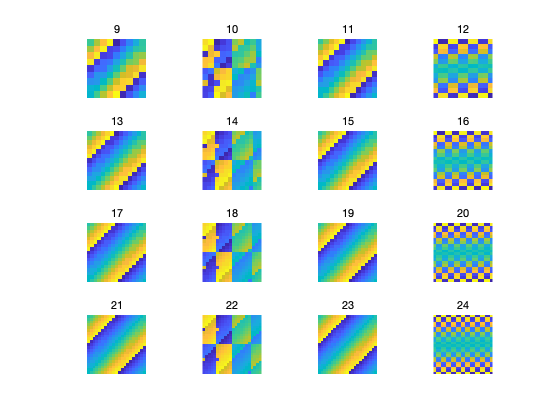

figure;
for n = 1:16
    subplot(4,4,n)
    ord = n+8;
    m = magic(ord);
    imagesc(m)
    title(num2str(ord))
    axis equal
    axis off
end

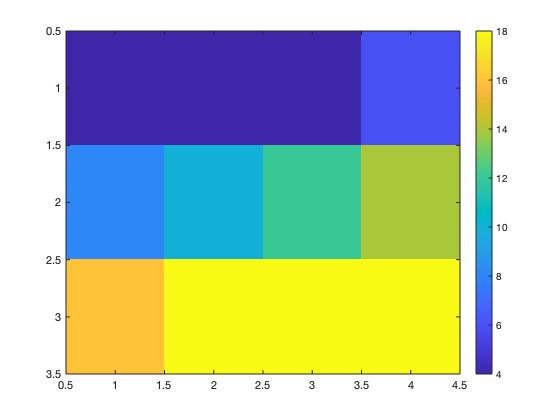

figure;
C = [0 2 4 6; 8 10 12 14; 16 18 20 22];
clims = [4 18];
imagesc(C,clims)
colorbar;

## Colormap

A colormap is a matrix of values that define the colors for graphics objects such as surface, image, and patch objects. MATLAB draws the objects by mapping data values to colors in the colormap.

Colormaps can be any length, but must be three columns wide. Each row in the matrix defines one color using an RGB triplet. An RGB triplet is a three-element row vector whose elements specify the intensities of the red, green, and blue components of the color. Typically, the intensities are `double` or `single` values in the range [0, 1]. A value of `0` indicates no color and a value of `1` indicates full intensity. For example, this command creates a colormap that has five colors: black, red, green, blue, and white.

Create a surface plot and set the colormap to `winter`.

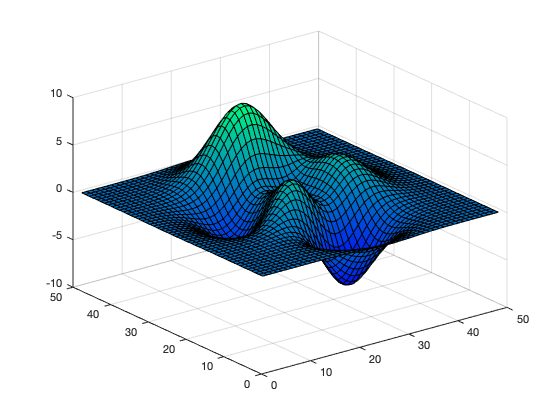

figure;
surf(peaks)
colormap winter

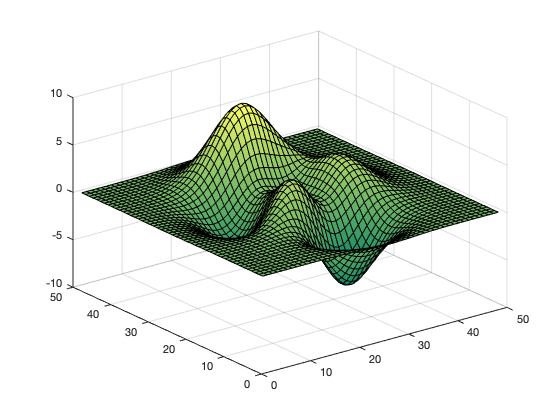

figure;
surf(peaks)
colormap summer

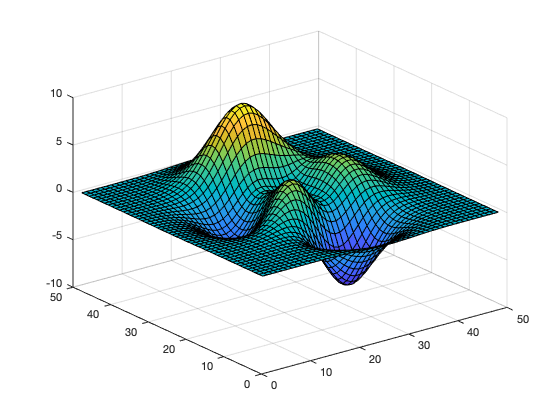

figure;
surf(peaks)
colormap default

col_1 = parula

col_1 =     0.2422    0.1504    0.6603
    0.2444    0.1534    0.6728
    0.2464    0.1569    0.6847
    0.2484    0.1607    0.6961
    0.2503    0.1648    0.7071
    0.2522    0.1689    0.7179
    0.2540    0.1732    0.7286
    0.2558    0.1773    0.7393
    0.2576    0.1814    0.7501
    0.2594    0.1854    0.7610


col_2 = hsv

col_2 =     1.0000         0         0
    1.0000    0.0234         0
    1.0000    0.0469         0
    1.0000    0.0703         0
    1.0000    0.0938         0
    1.0000    0.1172         0
    1.0000    0.1406         0
    1.0000    0.1641         0
    1.0000    0.1875         0
    1.0000    0.2109         0


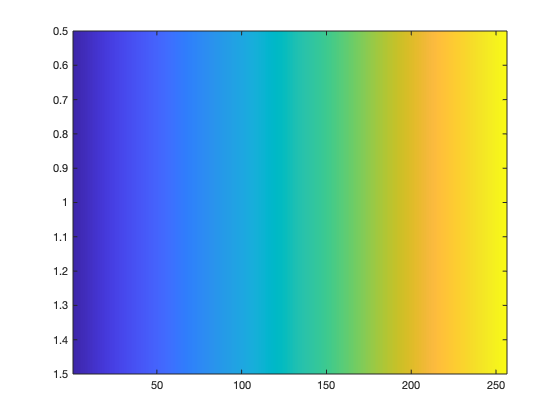

figure; 
imagesc(1:size(col_1,1))
colormap parula

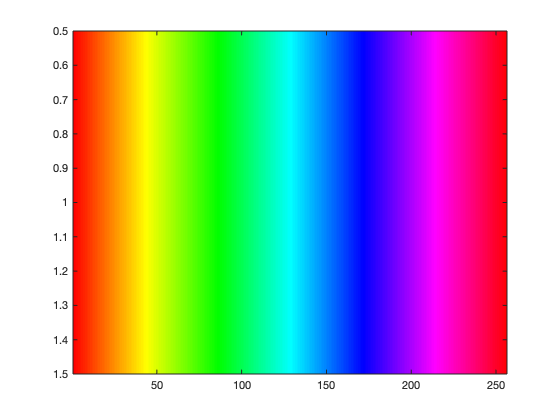

figure; 
imagesc(1:size(col_1,1))
colormap hsv

figure;
C = [0 2 4 6; 8 10 12 14; 16 18 20 22];
imagesc(C,clims)
colorbar

load(which('colormap_colorbrewer_wani.mat'));
col11_from_colorbrewer

col11_from_colorbrewer =     0.3686    0.3098    0.6353
    0.1961    0.5333    0.7412
    0.4000    0.7608    0.6471
    0.6706    0.8667    0.6431
    0.9020    0.9608    0.5961
    1.0000    1.0000    0.7490
    0.9961    0.8784    0.5451
    0.9922    0.6824    0.3804
    0.9569    0.4275    0.2627
    0.8353    0.2431    0.3098


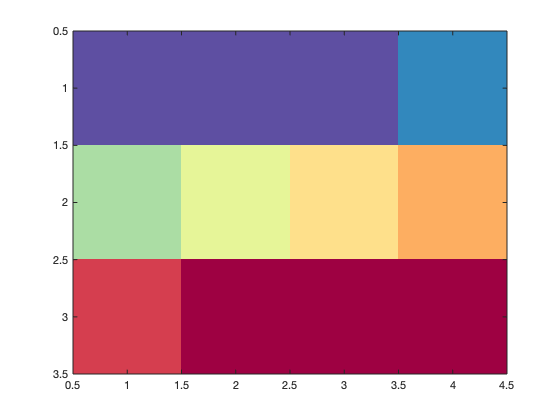

figure; imagesc(C,clims)
colormap(col11_from_colorbrewer)